# Transfer Learning Using GoogLeNet

This example shows how to use transfer learning to retrain GoogLeNet, a pretrained convolutional neural network, to classify a new set of images.

GoogLeNet has been trained on over a million images and can classify images into 1000 object categories (such as keyboard, coffee mug, pencil, and many animals). The network has learned rich feature representations for a wide range of images. The network takes an image as input, and then outputs a label for the object in the image together with the probabilities for each of the object categories.

Transfer learning is commonly used in deep learning applications. You can take a pretrained network and use it as a starting point to learn a new task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network from scratch with randomly initialized weights. You can quickly transfer learned features to a new task using a smaller number of training images.

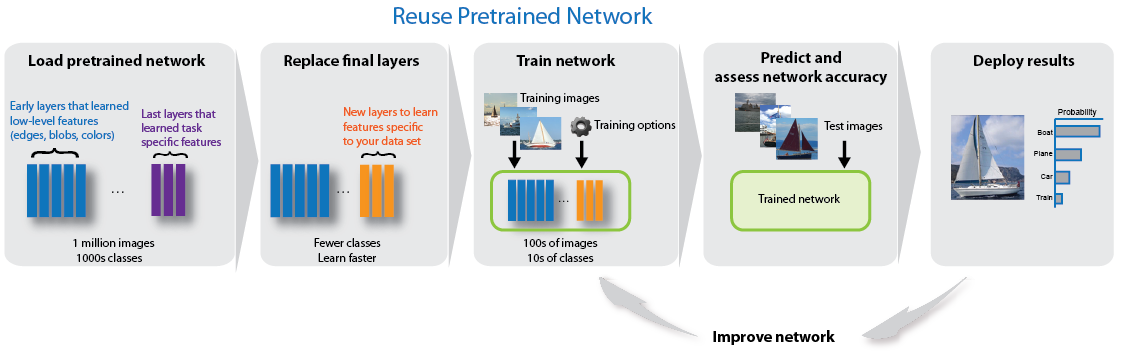

## Load Data

Unzip and load the new images as an image datastore. This very small data set contains only 75 images. Divide the data into training and validation data sets. Use 70% of the images for training and 30% for validation.

unzip('MerchData.zip');
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

## Load Pretrained Network

Load the pretrained GoogLeNet network. If the Neural Network Toolbox™ Model *for GoogLeNet Network* is not installed, then the software provides a download link.

net = googlenet;

Extract the layer graph from the trained network and plot the layer graph.

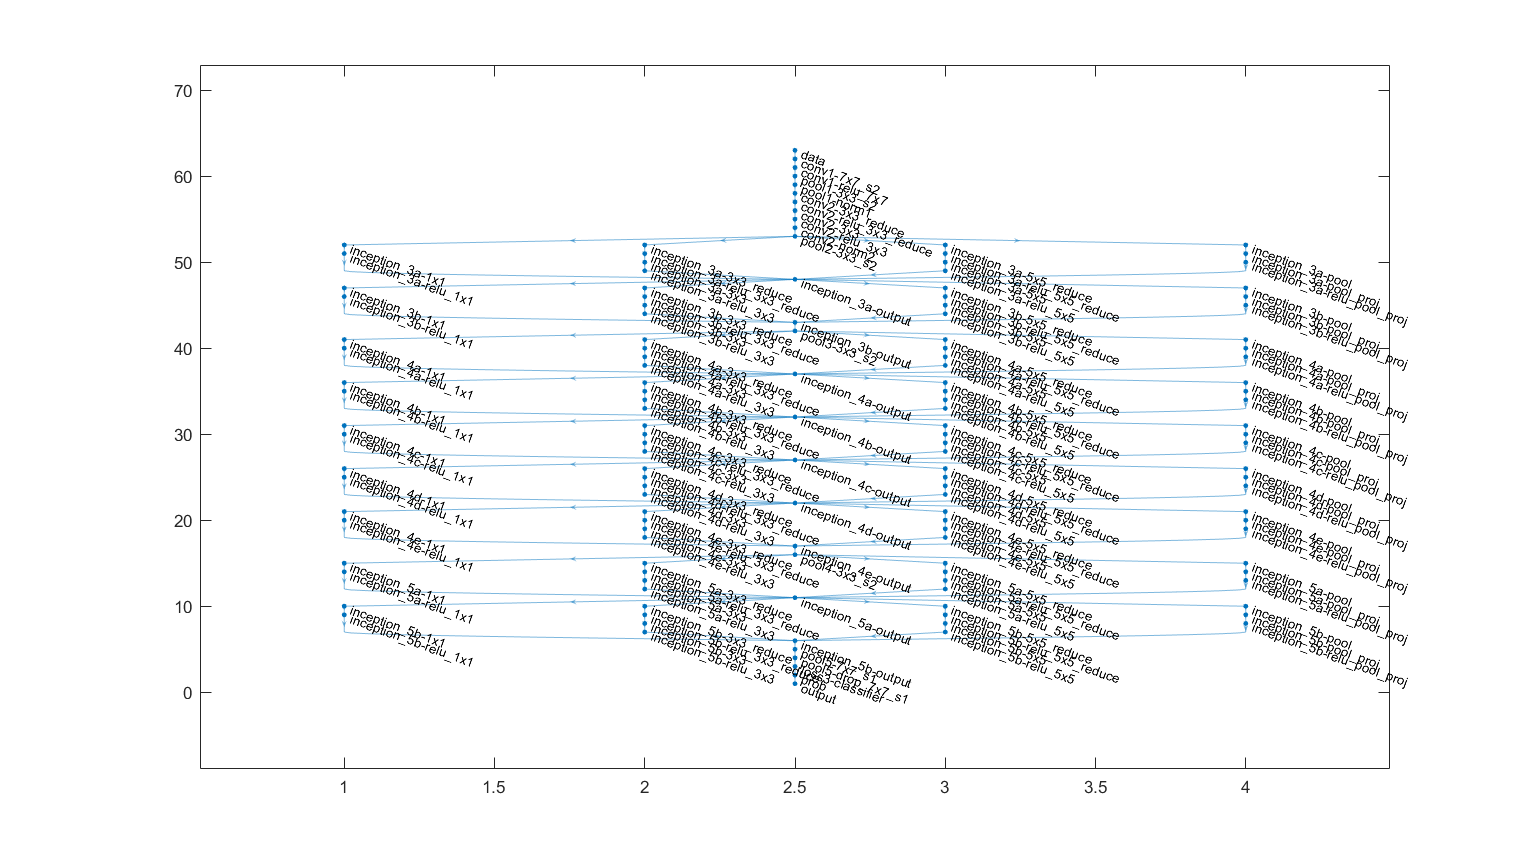

lgraph = layerGraph(net);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)

The first element of the `Layers` property of the network is the image input layer. This layer requires input images of size 224-by-224-by-3, where 3 is the number of color channels. 

net.Layers(1)

ans =   ImageInputLayer with properties:

                Name: 'data'
           InputSize: [224 224 3]

   Hyperparameters
    DataAugmentation: 'none'
       Normalization: 'zerocenter'


inputSize = net.Layers(1).InputSize;
net.Layers

ans =   144x1 Layer array with layers:

     1   'data'                           Image Input                   224x224x3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7x7x3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1x1x64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution                  

## Replace Final Layers

To retrain GoogLeNet to classify new images, replace the last three layers of the network. These three layers, `'loss3-classifier'`, `'prob'`, and `'output'`, contain information on how to combine the features that the network extracts into class probabilities and labels. Add three new layers to the layer graph: a fully connected layer, a softmax layer, and a classification output layer. Set the final fully connected layer to have the same size as the number of classes in the new data set (5, in this example). To learn faster in the new layers than in the transferred layers, increase the learning rate factors of the fully connected layer.

lgraph = removeLayers(lgraph, {'loss3-classifier','prob','output'});

numClasses = numel(categories(imdsTrain.Labels));
newLayers = [
    fullyConnectedLayer(numClasses,'Name','fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];
lgraph = addLayers(lgraph,newLayers);

Connect the last transferred layer remaining in the network (`'pool5-drop_7x7_s1'`) to the new layers. To check that the new layers are connected correctly, plot the new layer graph and zoom in on the last layers of the network.

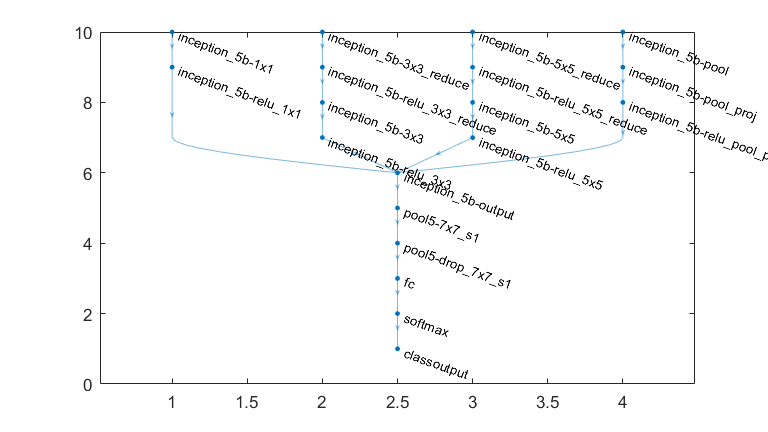

lgraph = connectLayers(lgraph,'pool5-drop_7x7_s1','fc');

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

## Freeze Initial Layers

The network is now ready to be retrained on the new set of images. Optionally, you can "freeze" the weights of earlier layers in the network by setting the learning rates in those layers to zero. During training, `trainNetwork` does not update the parameters of the frozen layers. Because the gradients of the frozen layers do not need to be computed, freezing the weights of many initial layers can significantly speed up network training. If the new data set is small, then freezing earlier network layers can also prevent those layers from overfitting to the new data set.

Extract the layers and connections of the layer graph and select which layers to freeze. In GoogLeNet, the first 110 layers are all the layers up to and including the *inception_5a* module. Use the supporting function [freezeWeights](matlab:edit(fullfile(matlabroot,'examples','nnet','main','freezeWeights.m'))) to set the learning rates to zero for the first 110 layers. Use the supporting function [createLgraphUsingConnections](matlab:edit(fullfile(matlabroot,'examples','nnet','main','createLgraphUsingConnections.m'))) to reconnect all the layers in the original order. The new layer graph contains the same layers, but with the learning rates of the earlier layers set to zero.

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:110) = freezeWeights(layers(1:110));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

The network requires input images of size 224-by-224-by-3, but the images in the image datastore have different sizes. Use an augmented image datastore to automatically resize the training images. Specify additional augmentation operations to perform on the training images: randomly flip the training images along the vertical axis, and randomly translate them up to 30 pixels horizontally and vertically. Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images.  

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

Specify the training options. Set `InitialLearnRate` to a small value to slow down learning in the transferred layers that are not already frozen. In the previous step, you increased the learning rate factors for the fully connected layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning in the new layers, slower learning in the middle layers, and no learning in the earlier, frozen layers. 

Specify the number of epochs to train for. When performing transfer learning, you do not need to train for as many epochs. An epoch is a full training cycle on the entire training data set. Specify the mini-batch size and validation data. The software validates the network every `ValidationFrequency` iterations during training.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'ValidationPatience',Inf, ...
    'Verbose',false ,...
    'Plots','training-progress');

Train the network using the training data. By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, `trainNetwork` uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`. Because the data set is so small, training is fast.

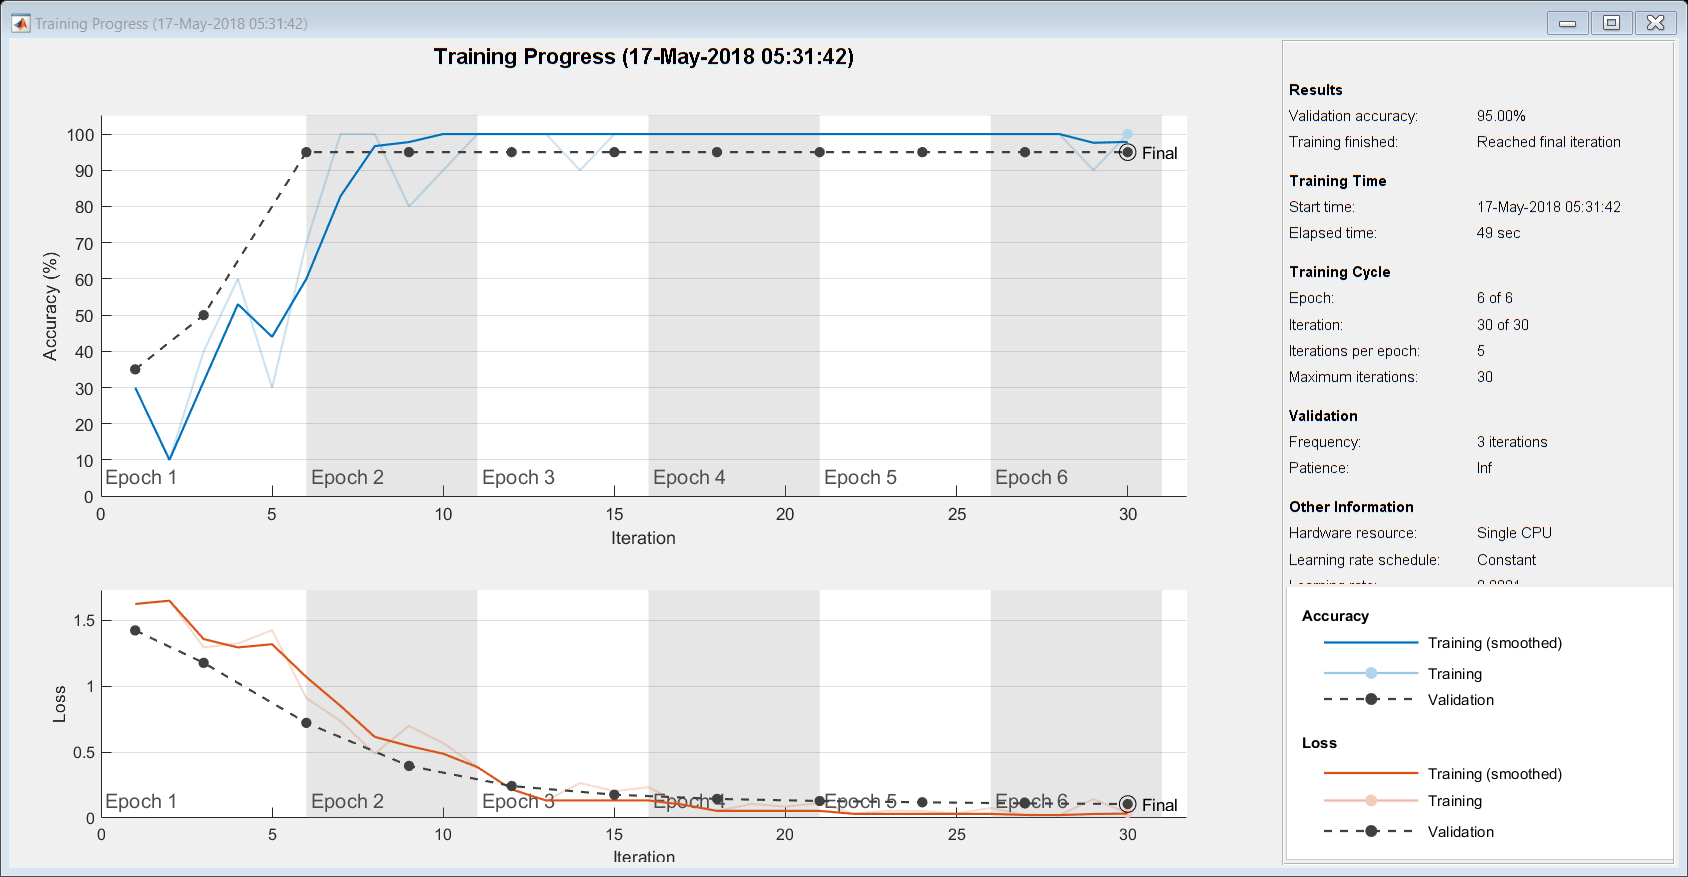

net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9500

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels.

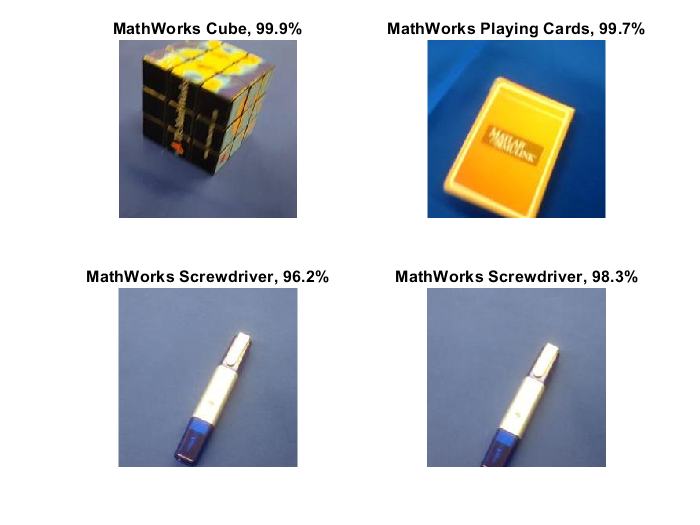

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end